# **電力ネットワークモデルの定義**

### **今回の演習では以下の画像に示すような「IEEE14busモデル」と呼ばれる系統モデルを解析対象にしてみます**

## **IEEE 14bus モデル**

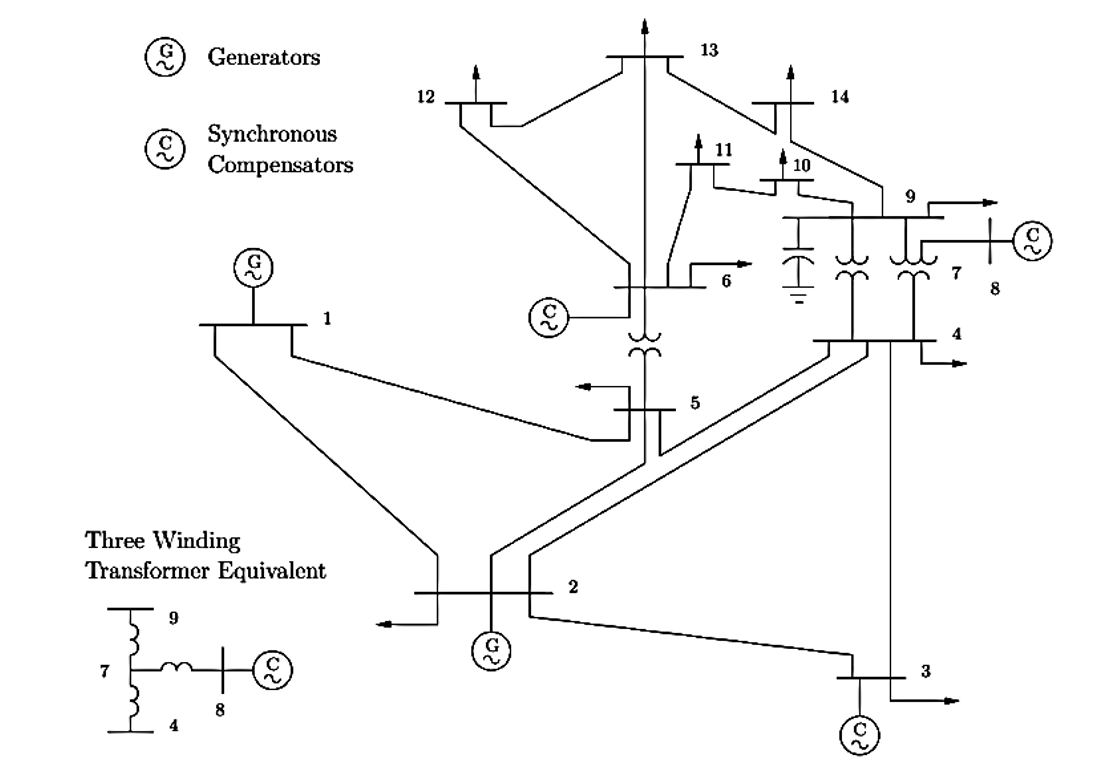

- 母線は全部で14個

- 母線1,2には同期発電機モデルが接続

- 母線3,6,8には同期調相機を接続

- 母線5-6,母線4-9,母線4-7-9の間に変圧器を接続

#### GUILDAに実装済みの標準モデルは以下のボタンから呼び出すことができます !!

net = network.IEEE14bus; 

INFO: Slack bus not found. Setting the first bus 'B001' as the slack bus.
INFO: B001 set as slack bus. 
      P and Q specifications for SG1B001 ignored in powerflow calculation.


disp("IEEE14母線系統を読み込みました.")

IEEE14母線系統を読み込みました.


base_bus = net.a_Bus([3,9,12,14]);
INV_past = repmat(2,[1,4]);
base_comp_name = ["LPQ2B003","LPQ1B009","LPQ1B012","LPQ1B014"];

# **系統の構成をいじってみよう !!**

## **図のように母線3,9,12,14ではGFM,GFLの選択ができるようになっています。**

## **自由に機器を選択して、系統の挙動がどのように変わるのか確認してみましょう。**

**※まずは、デフォルトの系統で実験してみることをお勧めします !!**

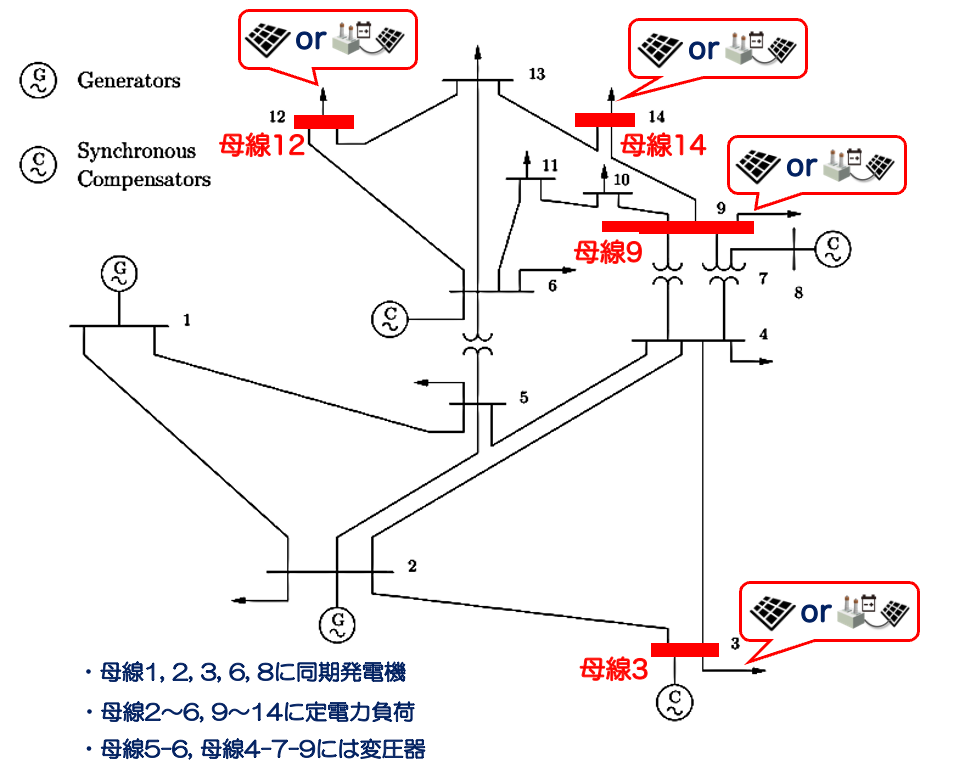

INV1 = 1;
INV2 = 1;
INV3 = 1;
INV4 = 1; 

inv_list = [INV1;INV2;INV3;INV4];

cmp_list = ["gen-classical";"load-power"];

tab_param = table(10,20,0.65,0.34, 'VariableNames', {'M','D','Xd','Xq'});
for inv = 1:numel(inv_list)
    if INV_past(inv) ~= inv_list(inv)
        % 変更する機器の名前
        base_name = base_comp_name(inv);
        % 新しく接続する機器
        new_comp  = cmp_list( inv_list(inv) );

        str_tagComp = string(base_bus{inv}.a_Component);

        % 機器を新しいものに付け替える
        base_bus{inv}.replace_component(base_name, new_comp,tab_param );    

        % 母線に接続されている機器のタグ
        l_new_tag = string(base_bus{inv}.a_Component);

        % 変更された機器のタグを取得
        comp_tag = l_new_tag(l_new_tag~=str_tagComp);
        base_comp_name(inv) = comp_tag;

        INV_past(inv) = inv_list(inv);
    end
end

net.initialize;
disp("変更が反映されました。実験に移りましょう !!")

変更が反映されました。実験に移りましょう !!


# **シミュレーションの実行**

## **地絡や解列を通して系統の挙動を数値的に観察してみましょう !!**

**※ 設定によっては解けない可能性があります。その場合は設定を変えてみましょう。**

# **a) 初期値応答**

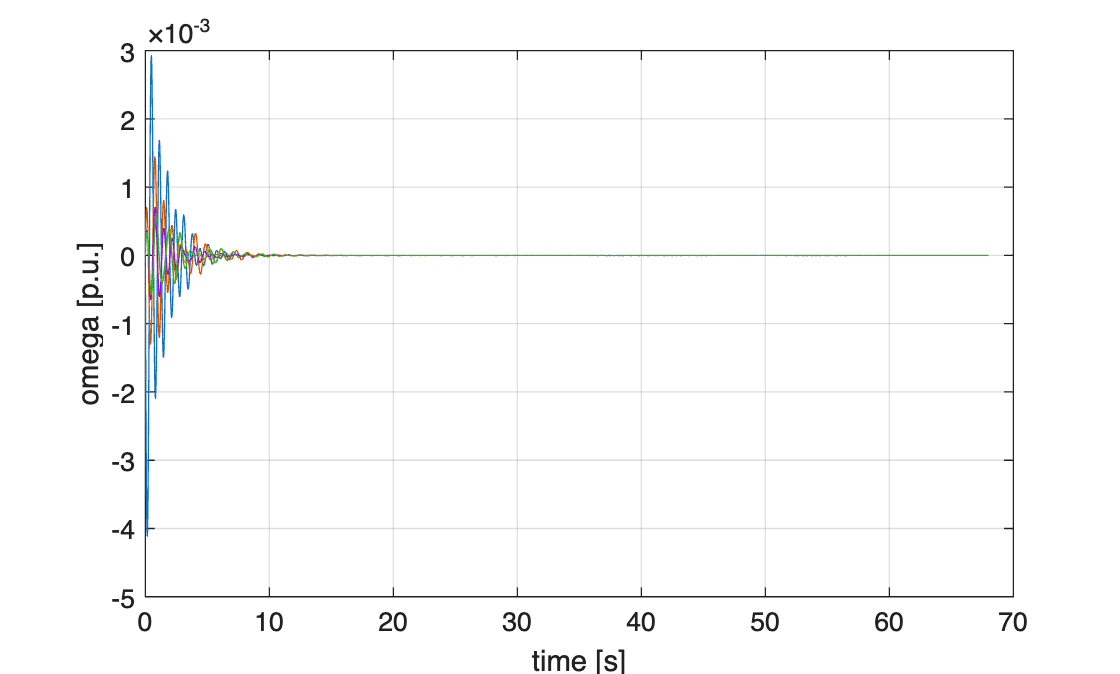

input_bus       = 1;
input_component = 1;
input_state = "delta";
input_value = 0.2;
simulation_time = 58; 

for i=1:numel(net.a_Bus)
    comp = net.a_Bus{i}.a_Component;
    for j=1:numel(comp)
        comp{j}.X_offset = zeros(size(comp{j}.str_x));
        comp{j}.U_offset = zeros(size(comp{j}.str_u));
    end
end

COMP = net.a_Bus{input_bus}.a_Component{input_component};
strx = COMP.str_x;

if input_component > numel(net.a_Bus{input_bus}.a_Component)
    disp(" >> 母線に接続されている機器の数よりも大きなインデックスを指定しているようです。" + newline + ...
         "    母線には機器が一つ接続されているか、機器が存在しない可能性があります。" +newline + ...
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return
end

if input_bus == 7
    disp(" >> 機器が接続されない母線を選択しているようです。" + newline + ...         
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return
end

if isempty(strx)
    disp(" >> 定電力負荷を選択しているようです。" + newline + ...
         "    定電力付加には状態変数が存在しません。"+ newline + ...
         "    上記の系統図を参考に同期発電機、もしくは同期調機を選択してみましょう !!")
    return
end

offsetX = zeros(size(strx));
offsetX(strx==input_state) = offsetX(strx==input_state) + input_value;

COMP.X_offset = reshape(offsetX, [], 1);

ev = eventset("Time", [0, simulation_time]);
o = odeSimulator(net, [0,simulation_time], ev);
[~, str] = o.simulate;

omg1 = str(1).X{1}.omega;
omg2 = str(2).X{1}.omega;
omg3 = str(3).X{1}.omega;
omg4 = str(6).X{1}.omega;
omg5 = str(8).X{1}.omega;

t = str(1).t;

plot(t, [omg1,omg2,omg3,omg4,omg5])
xlabel("time [s]")
ylabel("omega [p.u.]")

grid on

# **b) 入力応答**

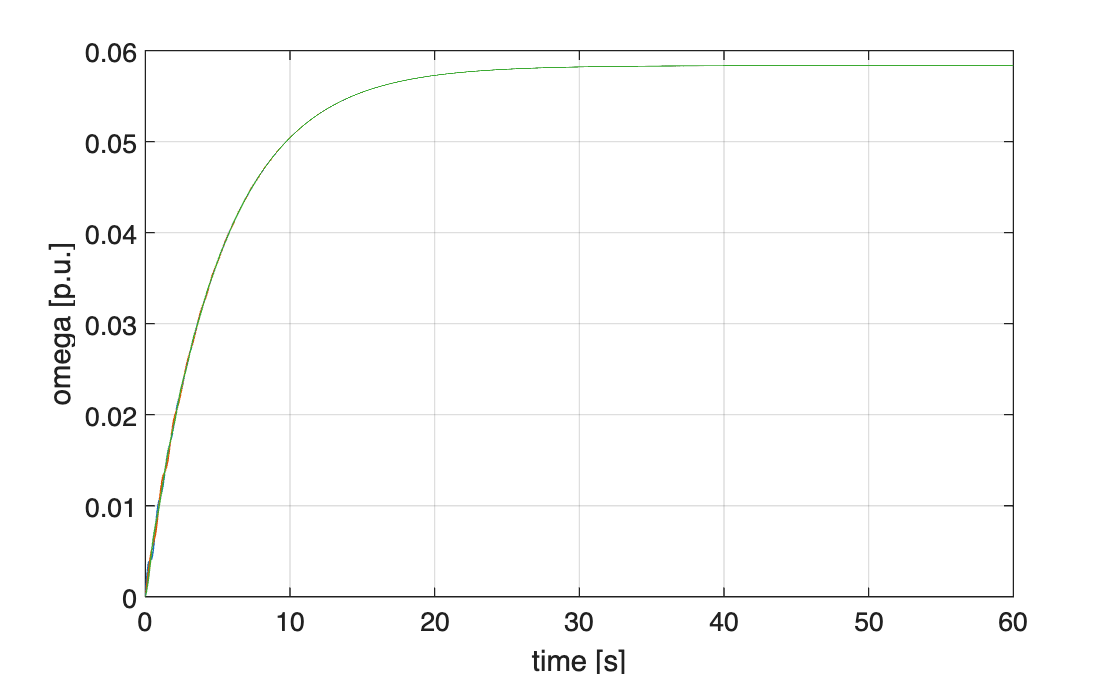

input_bus       = 2;
input_component = 1;
input_state = "Pload";
input_value = 0.1;
simulation_time = 50; 

for i=1:numel(net.a_Bus)
    comp = net.a_Bus{i}.a_Component;
    for j=1:numel(comp)
        comp{j}.X_offset = zeros(size(comp{j}.str_x));
        comp{j}.U_offset = zeros(size(comp{j}.str_u));
    end
end
if input_component > numel(net.a_Bus{input_bus}.a_Component)
    
    disp(" >> 母線に接続されている機器の数よりも大きなインデックスを指定しているようです。" + newline + ...
         "    母線には機器が一つ接続されているか、機器が存在しない可能性があります。" +newline + ...
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return    
end
comp = net.a_Bus{input_bus}.a_Component{input_component};
stru = comp.str_u;

if input_bus == 7
    disp(" >> 機器が接続されない母線を選択しているようです。" + newline + ...         
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return
end

if isa(comp, 'component.generator.abstract')
    if ~ismember(input_state, comp.str_u)
        disp(" >> どうやら負荷の入力を選択しているようですね。" + newline + ...
             "    同期機への入力はタービンからの入力である Pmech と励磁機からの入力である Vfield です。" + newline + ...
             "    これら二つの内、どちらか一方を選択してみましょう !!")
        return
    end
elseif isa(comp, 'component.load.abstract')
    if ~ismember(input_state, comp.str_u)
        disp(" >> どうやら同期機の入力を選択しているようですね。" + newline + ...
             "    負荷への入力は有効電力である Pload と無効電力である Qload です。" + newline + ...
             "    これら二つの内、どちらか一方を選択してみましょう !!")
        return
    end
end

offsetU = zeros(size(stru));
offsetU(stru==input_state) = offsetX(stru==input_state) + input_value;

comp.U_offset = reshape(offsetU, [], 1);

ev = eventset("Time", [0, simulation_time]);
o = odeSimulator(net, [0,simulation_time], ev);
[~, str] = o.simulate;

omg1 = str(1).X{1}.omega;
omg2 = str(2).X{1}.omega;
omg3 = str(3).X{1}.omega;
omg4 = str(6).X{1}.omega;
omg5 = str(8).X{1}.omega;

t = str(1).t;

plot(t, [omg1,omg2,omg3,omg4,omg5])
xlabel("time [s]")
ylabel("omega [p.u.]")

grid on

# **c) 地絡**

bus_number = 1;
simulation_time = 60;
fault_start_time = 10;
fault_time = 0.02; 

for i=1:numel(net.a_Bus)
    comp = net.a_Bus{i}.a_Component;
    for j=1:numel(comp)
        comp{j}.X_offset = zeros(size(comp{j}.str_x));
        comp{j}.U_offset = zeros(size(comp{j}.str_u));
    end
end


Fbus = net.a_Bus{bus_number}.str_tag;
ev = eventset("Time", fault_start_time+[0,fault_time], "FltBus", Fbus);
o = odeSimulator(net, [0,simulation_time], ev);
[~, str] = o.simulate;

Error using odeSimulator/simulate (line 558)
I couldn't solve this DAE system. Too bad !!


omg1 = str(1).X{1}.omega;
omg2 = str(2).X{1}.omega;
omg3 = str(3).X{1}.omega;
omg4 = str(6).X{1}.omega;
omg5 = str(8).X{1}.omega;

t = str(1).t;

plot(t, [omg1,omg2,omg3,omg4,omg5])
xlabel("time [s]")
ylabel("omega [p.u.]")

grid on

# **d) 解列**

bus_number = 2;
cmp_number = 2;
simulation_time = 91;
trip_start_time = 14;
trip_time = 0.1; 

for i=1:numel(net.a_Bus)
    comp = net.a_Bus{i}.a_Component;
    for j=1:numel(comp)
        comp{j}.X_offset = zeros(size(comp{j}.str_x));
        comp{j}.U_offset = zeros(size(comp{j}.str_u));
    end
end
s_bus_trip = net.a_Bus{bus_number};
n_com = numel(s_bus_trip.a_Component);

if cmp_number > numel(net.a_Bus{bus_number}.a_Component)
    if ~isa(net.a_Bus{bus_number}.a_Component{end}, 'component.load.abstract')
        disp(" >> 母線に接続されている機器の数よりも大きなインデックスを指定しているようです。" + newline + ...
             "    母線には機器が一つ接続されているか、機器が存在しない可能性があります。" +newline + ...
             "    上記の系統図を参考に設定を見直してみましょう !!")
        return
    end    
end

if bus_number == 7
    disp(" >> 機器が接続されない母線を選択しているようです。" + newline + ...         
         "    上記の系統図を参考に設定を見直してみましょう !!")
    return
end



if isscalar(net.a_Bus{bus_number}.a_Component)
    comp = net.a_Bus{bus_number}.a_Component{1};
    if isa(comp, 'component.generator.abstract')
        if cmp_number == 2
            disp(" >> どうやら負荷を選択しているようです。" + newline + ...
                 "    この母線、実は同期機しか接続されていないんです。" + newline + ...
                 "    設定をもう一度見直してみましょう !!")
            return
        end
    elseif isa(comp, 'component.load.abstract')
        if cmp_number == 1
            disp(" >> どうやら同期発電機か同期調相機を選択しているようですね。" + newline + ...
                 "    この母線、実は負荷しか接続されていないんです。" + newline + ...             
                 "    設定をもう一度見直してみましょう !!")
            return
        end
    end
else
    comp = net.a_Bus{bus_number}.a_Component{cmp_number};
end

Tcmp = comp.str_tag;

ev = eventset("Time", trip_start_time+[0,trip_time], "TrpCmp", Tcmp);
o = odeSimulator(net, [0,simulation_time], ev);
try
    [~, str] = o.simulate;
catch ME
    disp(" >> このシミュレーション設定ではソルバーが解を出せないようです。" + newline + ...
         "    もう少し優しくしてあげてください。お願いしますっっ !!")
end

 >> このシミュレーション設定ではソルバーが解を出せないようです。
    もう少し優しくしてあげてください。お願いしますっっ !!


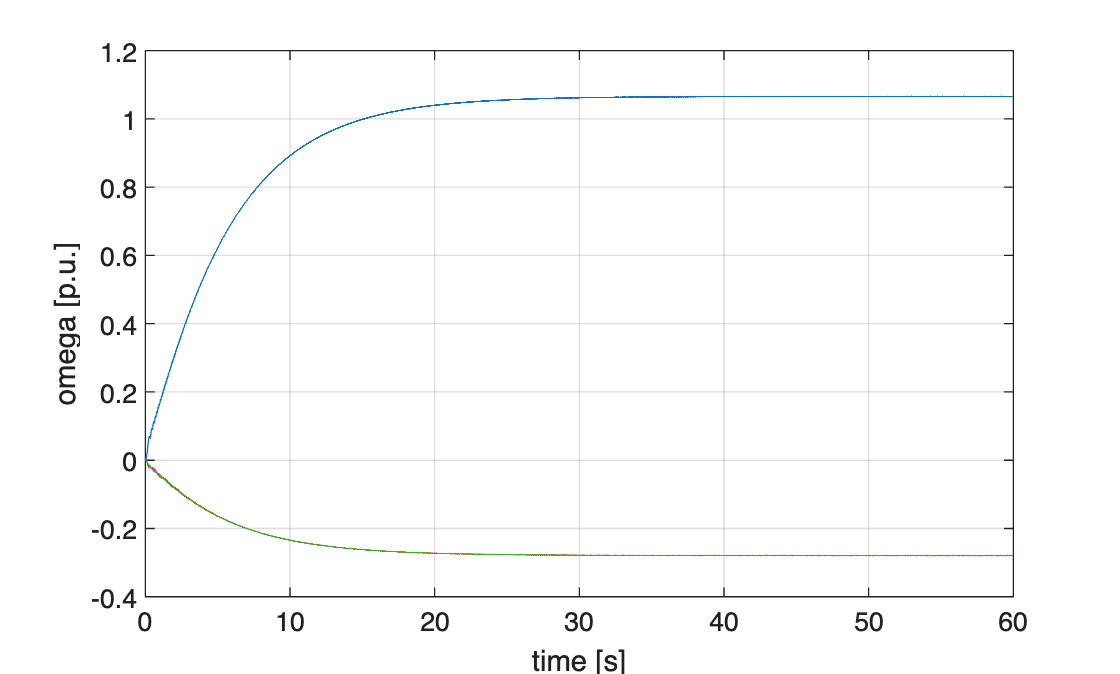


omg1 = str(1).X{1}.omega;
omg2 = str(2).X{1}.omega;
omg3 = str(3).X{1}.omega;
omg4 = str(6).X{1}.omega;
omg5 = str(8).X{1}.omega;

t = str(1).t;

plot(t, [omg1,omg2,omg3,omg4,omg5])
xlabel("time [s]")
ylabel("omega [p.u.]")

grid on

## 応答結果の見方

上のグラフは周波数偏差($\omega$:omega)の応答になります．

周波数偏差の単位は p.u. です．

電力系統の交流電源は関西では60Hz, 関東では50Hzで運用されています．

例えば60Hzで運用されている系統で周波数が61Hzとなっている場合，周波数偏差は以下のようになります．


$$\frac{61{\rm [Hz]}- 60{\rm [Hz]}}{60{\rm [Hz]}}=0.016 [pu]$$


つまり上の応答は0であることが望ましいということになります．

# **シミュレーション結果を解析**

**今回の演習では，各発電機のL２ノルムの大きさで性能を評価します**

**上記の解析で得られた変数「out」の内部のデータを処理することで計算できます．**

**処理の内容は末尾で定義している関数「culculate_l2norm」の部分を見てみてください！！**

L2norm_mat = culculate_l2norm(str); 


各発電機の周波数偏差のL２ノルム(大きい順) 

同期発電機01のl2ノルム: 0.00037064
同期発電機02のl2ノルム: 0.0003507
同期調相機05のl2ノルム: 0.00033397
同期調相機04のl2ノルム: 0.00033278
同期調相機03のl2ノルム: 0.0003313


# **＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝**

# **次に、GFM・GFL最適選択にチャレンジしてみましょう !!**

# 付録:

## １．出力結果のデータ構造

        によって出力されたデータ "out" にはシミュレーションの様々な解析結果が格納されています．

        今回解析を行いたい各発電機の周波数偏差('omega')の時系列データは

        とすることで得られます．

        一方でシミュレーション中のサンプリング時間のデータは以下のようにして取得することが出来ます．

        つまり，例えば以下のように実行することで発電機1の周波数偏差の応答をプロットすることが出来ます！

## ２．応答データのL２ノルムの計算の仕方

        L2ノルムの定義

###         L2norm = $\sqrt{\int x^2 dt}$

        ただし，シミュレーションなどの数値解析によって得られるデータは離散データなので，$\int x^2 dt
$　のような計算はできません．

        Matlabでは，離散データから台形法を用いて積分を行う関数 "trapz" があります.　(詳細は[公式HP](https://jp.mathworks.com/help/matlab/ref/trapz.html)を参考)

        よって例えば，上記の１．で得られた 'time_data' と 'omega_1' からomega_1のL2ノルムを得る場合は以下のように実行すれば良いです

- 
$$omega1square = omega1^2 $$


- 
$$integer = \int (omega1squar ) dt$$


- 
$$L2 = \sqrt{integer}$$
                

### 以上の処理をまとめたのが下の関数です！

function L2 = culculate_l2norm(str)
    L2 = zeros(1,5);                       %データ格納用の行列を定義
    fprintf('\n各発電機の周波数偏差のL２ノルム(大きい順) \n\n')

    c_num = [1,2,3,6,8];
    %IEEE68busは母線1~16に同期発電機が付加されている．
    for i = 1:numel(c_num)    
        t        = str(c_num(i)).t;
        omega_i  = str(c_num(i)).X{1}.omega;       % 母線iの周波数偏差の応答データを抽出
        omega2_i = omega_i.^2;              % 応答データの各要素を２乗する
        integer  = trapz(t, omega2_i);      % ２乗したデータを数値積分する
        L2_i     = sqrt(integer);           % 積分値の平方根を取りL２ノルムを計算
        L2(i)    = L2_i;                    % 得られたL2ノルムを配列に格納する
    end
    [~, idx_sort] = sort(L2,'descend');     %L2ノルムの大きい順にソートした機器の番号を得る
    
    strstr = {'同期発電機','同期発電機','同期調相機','同期調相機','同期調相機'};
    for i = idx_sort
        disp([strstr{i},num2str(i,'%.2d'),'のl2ノルム: ',num2str(L2(i))])
    end
end

